**multiplexer ground**

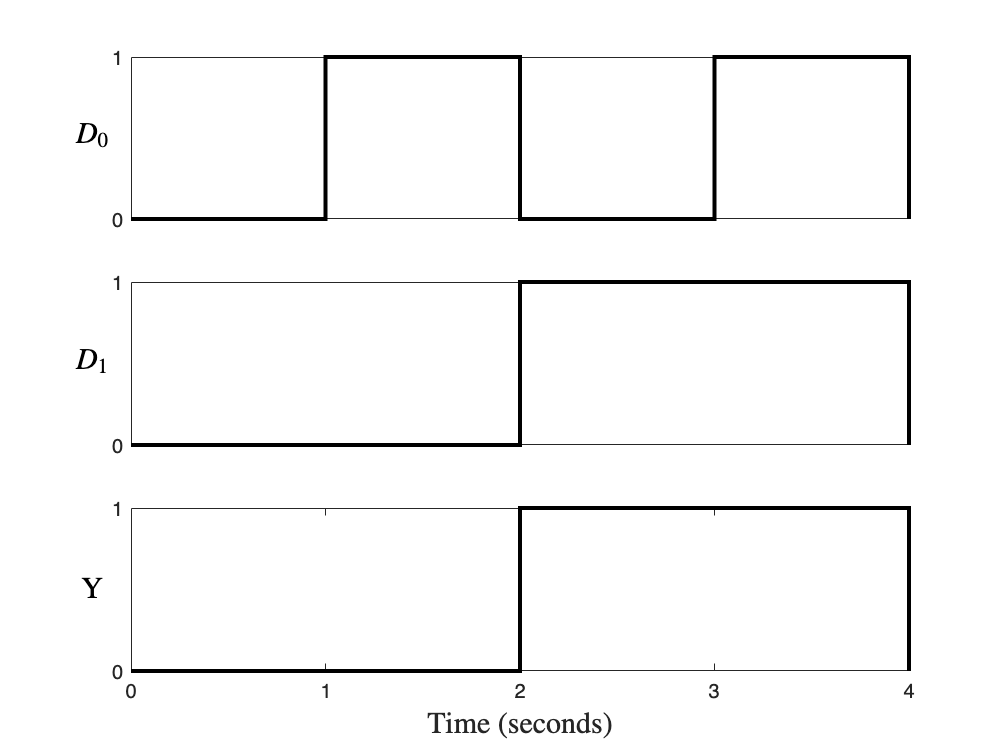

time = 0:1:4; 

%Data
input1 = [0 1 0 1 0]; 
input2 = [0 0 1 1 0]; 
output = [0 0 1 1 0]; 


figure;
%Plotting the input 1 signal
subplot(3,1,1);
stairs(time, input1, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input 1');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$D_0$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the input 2 signal
subplot(3,1,2);
stairs(time, input2, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$D_1$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output
subplot(3,1,3);
stairs(time, output, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks(0:1:4); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3', '4'}); % Set the x-axis labels for the Q' subplot
title('Y', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time (seconds)','Interpreter', 'latex', 'FontSize',15);
%Saving the image
saveas(gcf, 'multiplexer_ground.png');

**multiplexer 5V**

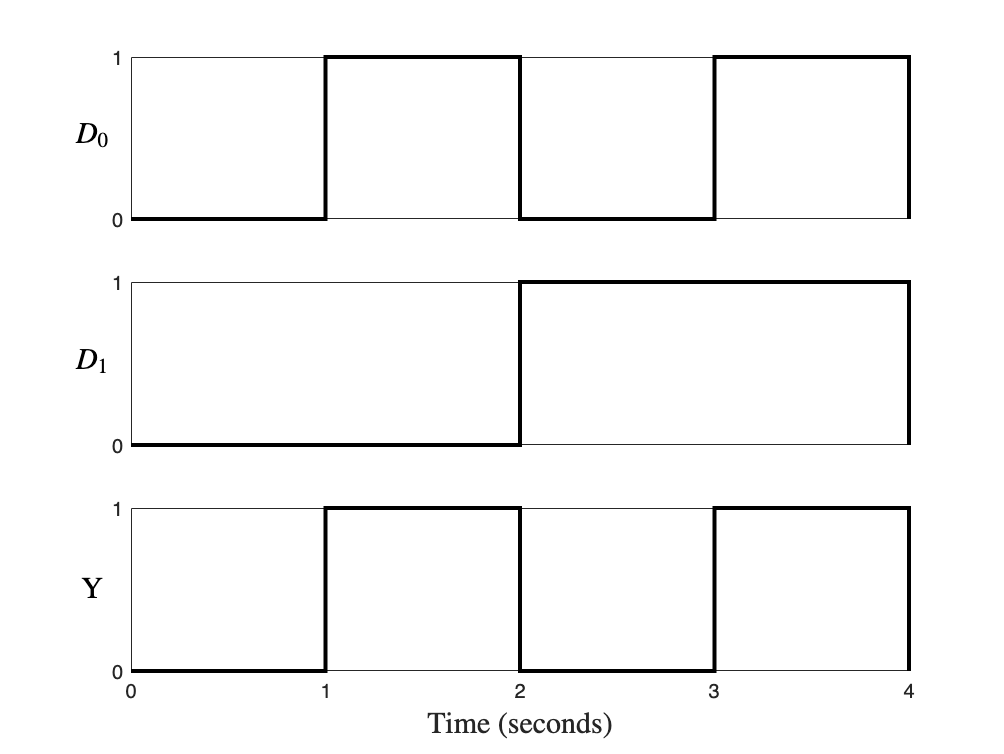


time = 0:1:4; 

%Data
input1 = [0 1 0 1 0]; 
input2 = [0 0 1 1 0]; 
output = [0 1 0 1 0]; 


figure;
%Plotting the input 1 signal
subplot(3,1,1);
stairs(time, input1, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input 1');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$D_0$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the input 2 signal
subplot(3,1,2);
stairs(time, input2, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$D_1$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output
subplot(3,1,3);
stairs(time, output, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks(0:1:4); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3', '4'}); % Set the x-axis labels for the Q' subplot
title('Y', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time (seconds)','Interpreter', 'latex', 'FontSize',15);
%Saving the image
saveas(gcf, 'multiplexer_5v.png');

**demultiplexer 5V**

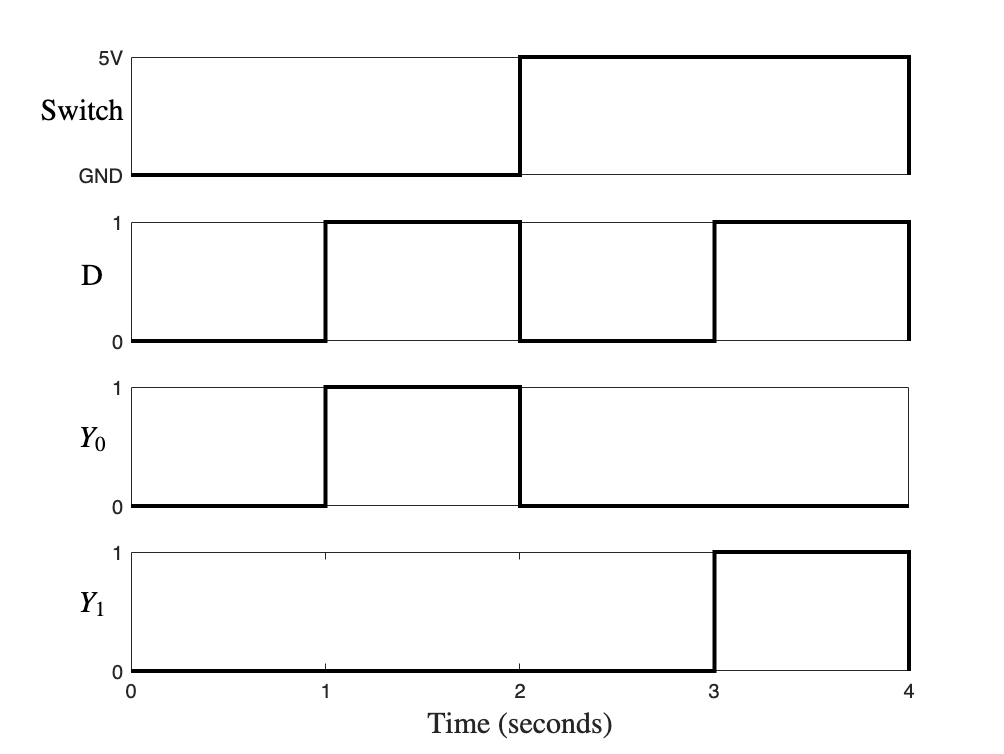

time = 0:1:4; 

%Data
s = [0 0 1 1 0];
input1 = [0 1 0 1 0]; 
output1 = [0 1 0 0 0]; 
output2 = [0 0 0 1 0]; 


figure;
%Plotting the S
subplot(4,1,1);
stairs(time, s, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input');
set(gca, 'YTick', [0 1], 'YTickLabel', {'GND', '5V'});
xticks([]);
title('Switch', 'Position', [-0.25, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

%Plotting the input signal
subplot(4,1,2);
stairs(time, input1, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('D', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output 1 signal
subplot(4,1,3);
stairs(time, output1, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Y_0$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output 2
subplot(4,1,4);
stairs(time, output2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks(0:1:4); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3', '4'}); % Set the x-axis labels for the Q' subplot
title('$Y_1$', 'Position', [-0.2, 0.4],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time (seconds)','Interpreter', 'latex', 'FontSize',15);
%Saving the image
saveas(gcf, 'demultiplexer.png');

**connected**

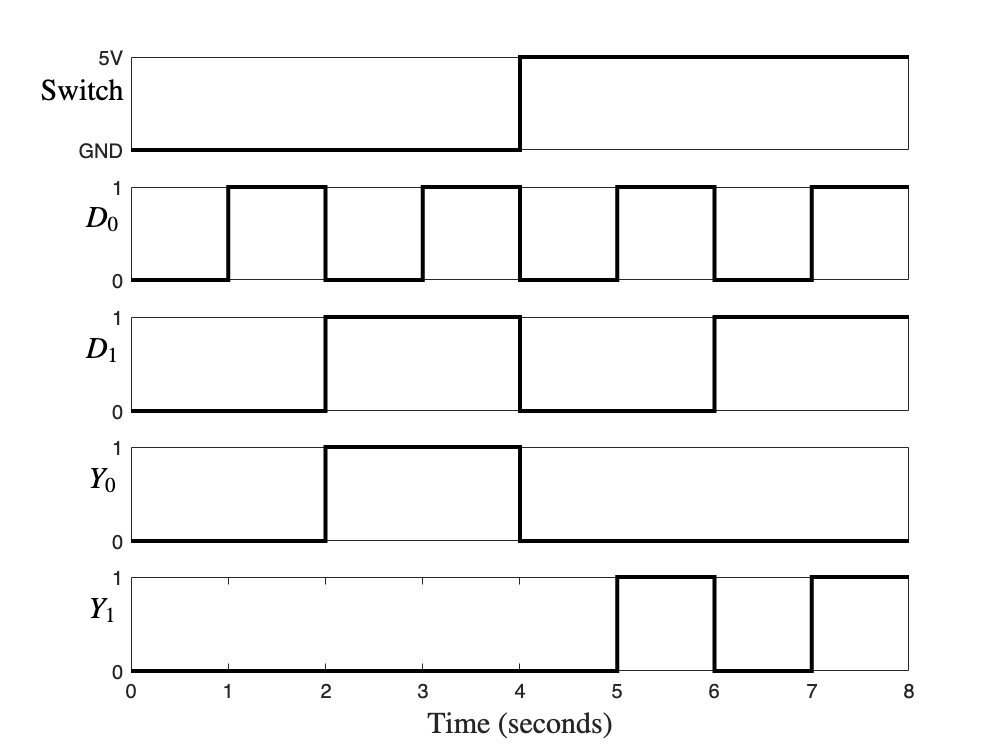

time = 0:1:8; 

%Data
select = [0 0 0 0 1 1 1 1 1];
input1 = [0 1 0 1 0 1 0 1 1]; 
input2 = [0 0 1 1 0 0 1 1 1];
output1 = [0 0 1 1 0 0 0 0 0]; 
output2 = [0 0 0 0 0 1 0 1 1]; 


figure;
%Plotting the S
subplot(5,1,1);
stairs(time, select, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input');
set(gca, 'YTick', [0 1], 'YTickLabel', {'GND', '5V'});
xticks([]);
title('Switch', 'Position', [-0.5, 0.45],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

%Plotting the input signal
subplot(5,1,2);
stairs(time, input1, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$D_0$', 'Position', [-0.3, 0.45],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

subplot(5,1,3);
stairs(time, input2, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Input');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$D_1$', 'Position', [-0.3, 0.45],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output 1 signal
subplot(5,1,4);
stairs(time, output1, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Y_0$', 'Position', [-0.3, 0.45],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the output 2
subplot(5,1,5);
stairs(time, output2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks(0:1:9); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3', '4', '5', '6', '7', '8'}); % Set the x-axis labels for the Q' subplot
title('$Y_1$', 'Position', [-0.3, 0.45],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time (seconds)','Interpreter', 'latex', 'FontSize',15);
%Saving the image
saveas(gcf, 'connectedmuxdemux.png');